# TCLab Heater Actuators

**Objective: **Develop and test an FOPDT model for heater 2 and temperature 2 from information about the TCLab actuators (TIP31C transistor heaters).

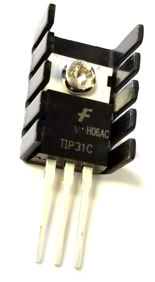

The TCLab actuators are transistor heaters (TIP31C NPN Bipolar Junction Transistors) in package form TO-220. TIP31C BJT transistors are not commonly used as heaters but can expel heat when used in power, audio, and ON/OFF switch applications. To avoid the power loss and subsequent heat generation, a MOSFET transistor is a lower power alternative. If a MOSFET were used instead, it would control the ON/OFF to a resistive power heater. Because the TIP31C does dissipate power, it acts as the heater and the switch. The TIP31C heater is controlled through Pulse Width Modulation (PWM). PWM is one method to emulate an analog output with a digital (ON/OFF) switch. The Arduino cycles from 0 to 100% in rapid succession (500 Hz or every 2 milliseconds). The digital output is 8-bits with 28 discrete levels represented as integers between 0 and 255. The transistor heater can be set between 0 and 100% output by the Arduino such as Q1 to 65% for 10 seconds and Q2 to 85% for 5 seconds.

clc; clear all; close all;
lab = tclab;
lab.T1

ans = 23.3138

lab.Q1(65);
pause(10);
lab.T1

ans = 23.8025

lab.Q2(85);
lab.T2

ans = 24.5357

pause(5);
lab.T2

ans = 24.1935

lab.off();
clear lab;

The maximum power output of the heater with a 5V power supply is about 1 Watt. Some of the power from the supply is dissipated over the power cable wire that has a thickness of 20 American Wire Gauge (AWG). The power cable connects the USB power source (either a computer port or the power supply) to the TCLab shield to provide a source for the heat generation. The TCLab has two heaters ($Q_1$ and $Q_2
$). The heaters are set to different power levels in the Arduino firmware. This is by design to make the gain for heater 1 and heater 2 different. When heater 1 is set to 100%, a signal of 200 out of 255 is sent to the Arduino. When heater 2 is set to 100%, a signal of 100 out of 255 is sent to the Arduino for half the power of heater 1.

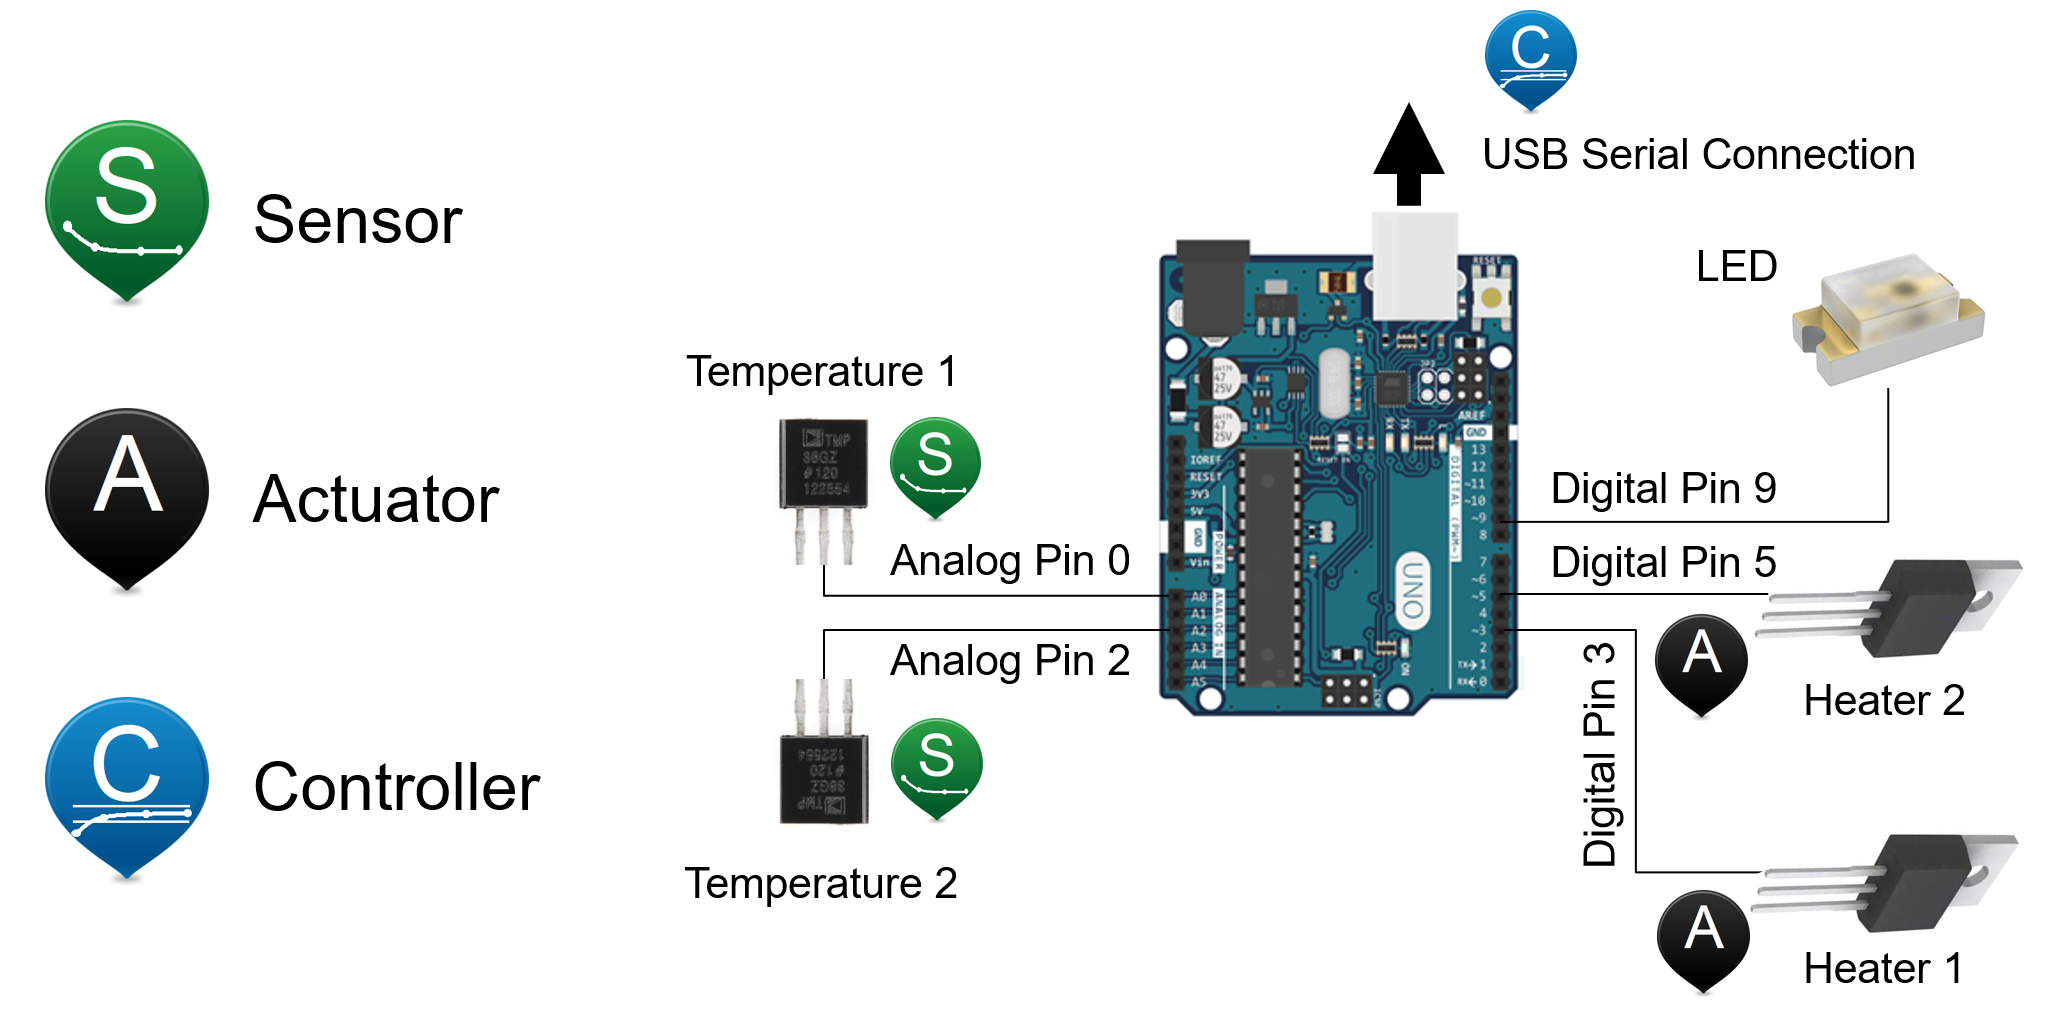

Given the FOPDT constants below for heater 1, determine the FOPDT constants for heater 2 from the information above. Then, evaluate the derived model with a step test to compare measured and predicted values.

viewSolution(false)

FOPDT Constants for heater 1:

    Gain: $0.9 \frac{^\circ C}{\% Power}$

    Process Time Constant: $175.0 \text{ seconds}$

    Dead Time: $15.0 \text{ seconds}$

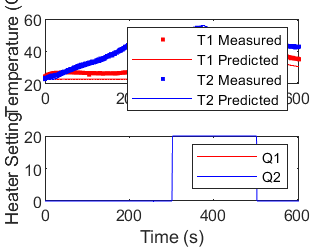

% Heater 1 Model
Kp1 = 0.9;       % deg C/ %
tauP1 = 175.0;   % seconds
thetaP1 = 15.0;  % seconds

% Heater 2 Model
Kp2 = Kp1 / 2;     % deg C / %
tauP2 = tauP1;     % seconds
thetaP2 = thetaP1; % seconds

% initialize arrays for storage
n = 600;
tm_ = zeros(n, 1);  % Time (s)
Q1_ = zeros(n, 1);  % Heater 1 Setting
Q1_(300:500) = 20.0;
Q2_ = zeros(n, 1);  % Heater 2 Setting
Q2_(10:120) = 50.0;
Q2_(120:360) = 90.0;
Q2_(360:end) = 30.0;
T1p_ = ones(n, 1) * 23.0;  % Temperature 1 Predicted from FOPDT
T1_ = ones(n, 1) * 23.0;  % Temperature 1 simulated with tclab
T2p_ = ones(n, 1) * 23.0;  % Temperature 2 Predicted from FOPDT
T2_ = ones(n, 1) * 23.0;  % Temperature 2 simulated with tclab

try
    figure();
    lab = tclab;
    tic;
    for i = 2:n-1
        tm_(i) = toc;
        dt = tm_(i) - tm_(i-1);
        T1_(i) = lab.T1;
        T2_(i) = lab.T2;
        lab.Q1(Q1_(i));
        lab.Q2(Q2_(i));

        % Simulate time step FOPDT explicitly
        z = exp(-dt/tauP1);
        Q1i = max(1, round(i - thetaP1));
        T1p_(i) = (T1p_(i-1)-23.0) * z + (Q1_(Q1i)) * (1-z) * Kp1 + 23.0;
        Q2i = max(1, round(i - thetaP2));
        T2p_(i) = (T2p_(i-1)-23.0) * z + (Q2_(Q2i)) * (1-z) * Kp2 + 23.0;

        subplot(2,1,1)
        plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName', 'T1 Measured')
        hold on
        plot(tm_(1:i), T1p_(1:i), 'r-', 'DisplayName', 'T1 Predicted')
        hold on
        plot(tm_(1:i), T2_(1:i), 'b.', 'DisplayName', 'T2 Measured')
        hold on
        plot(tm_(1:i), T2p_(1:i), 'b-', 'DisplayName', 'T2 Predicted')
        hold off
        legend
        ylabel('Temperature (C)')
        subplot(2,1,2)
        plot(tm_(1:i), Q1_(1:i), 'r-', 'DisplayName','Q1')
        hold on
        plot(tm_(1:i), Q2_(1:i), 'b-', 'DisplayName','Q2')
        hold off
        legend
        ylabel('Heater Setting')
        xlabel('Time (s)')

        pause(1-mod(toc,1))
    end
catch
    lab.off
    clear lab
end

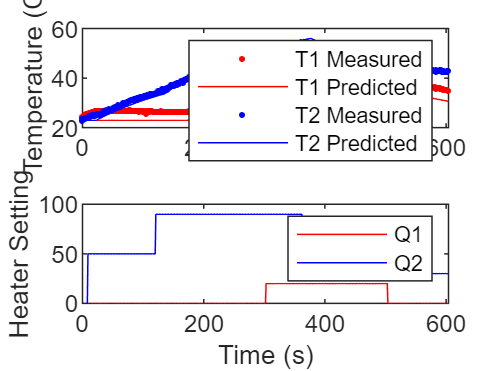

subplot(2,1,1)
plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName', 'T1 Measured')
hold on
plot(tm_(1:i), T1p_(1:i), 'r-', 'DisplayName', 'T1 Predicted')
hold on
plot(tm_(1:i), T2_(1:i), 'b.', 'DisplayName', 'T2 Measured')
hold on
plot(tm_(1:i), T2p_(1:i), 'b-', 'DisplayName', 'T2 Predicted')
hold off
legend
ylabel('Temperature (C)')
subplot(2,1,2)
plot(tm_(1:i), Q1_(1:i), 'r-', 'DisplayName','Q1')
hold on
plot(tm_(1:i), Q2_(1:i), 'b-', 'DisplayName','Q2')
hold off
legend
ylabel('Heater Setting')
xlabel('Time (s)')

### Solution

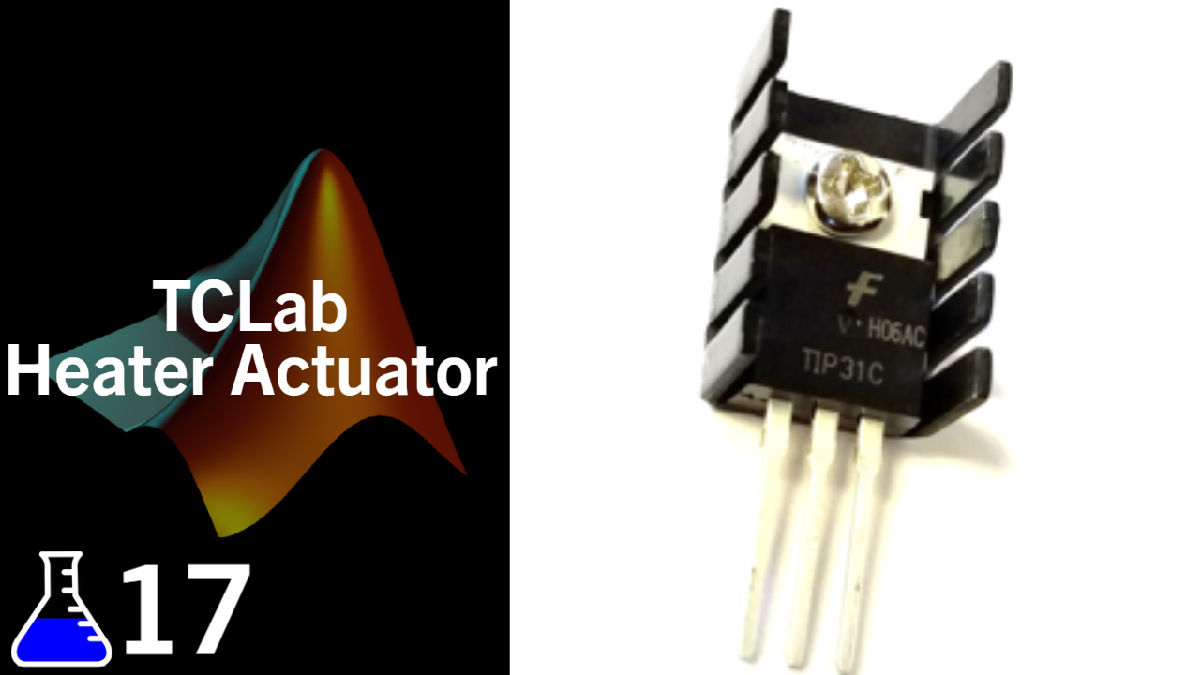

### [View Solution Video](https://youtu.be/juk_uxlXErs)

function viewSolution(view)
if view
	disp("% Heater 1 Model" + newline + ...
	     "Kp1 = 0.9;       % deg C/ %" + newline + ...
	     "tauP1 = 175.0;   % seconds" + newline + ...
	     "thetaP1 = 15.0;  % seconds" + newline + ...
	     "" + newline + ...
	     "% Heater 2 Model" + newline + ...
	     "Kp2 = Kp1 / 2;     % deg C / %" + newline + ...
	     "tauP2 = tauP1;     % seconds" + newline + ...
	     "thetaP2 = thetaP1; % seconds" + newline + ...
	     "" + newline + ...
	     "% initialize arrays for storage" + newline + ...
	     "n = 600;" + newline + ...
	     "tm_ = zeros(n, 1);  % Time (s)" + newline + ...
	     "Q1_ = zeros(n, 1);  % Heater 1 Setting" + newline + ...
	     "Q1_(300:500) = 20.0;" + newline + ...
	     "Q2_ = zeros(n, 1);  % Heater 2 Setting" + newline + ...
	     "Q2_(10:120) = 50.0;" + newline + ...
	     "Q2_(120:360) = 90.0;" + newline + ...
	     "Q2_(360:end) = 30.0;" + newline + ...
	     "T1p_ = ones(n, 1) * 23.0;  % Temperature 1 Predicted from FOPDT" + newline + ...
	     "T1_ = ones(n, 1) * 23.0;  % Temperature 1 simulated with tclab" + newline + ...
	     "T2p_ = ones(n, 1) * 23.0;  % Temperature 2 Predicted from FOPDT" + newline + ...
	     "T2_ = ones(n, 1) * 23.0;  % Temperature 2 simulated with tclab" + newline + ...
	     "" + newline + ...
	     "try" + newline + ...
	     "    figure();" + newline + ...
	     "    lab = tclab;" + newline + ...
	     "    tic;" + newline + ...
	     "    for i = 2:n-1" + newline + ...
	     "        tm_(i) = toc;" + newline + ...
	     "        dt = tm_(i) - tm_(i-1);" + newline + ...
	     "        T1_(i) = lab.T1;" + newline + ...
	     "        T2_(i) = lab.T2;" + newline + ...
	     "        lab.Q1(Q1_(i));" + newline + ...
	     "        lab.Q2(Q2_(i));" + newline + ...
	     "        " + newline + ...
	     "        % Simulate time step FOPDT explicitly" + newline + ...
	     "        z = exp(-dt/tauP1);" + newline + ...
	     "        Q1i = max(1, round(i - thetaP1));" + newline + ...
	     "        T1p_(i) = (T1p_(i-1)-23.0) * z + (Q1_(Q1i)) * (1-z) * Kp1 + 23.0;" + newline + ...
	     "        Q2i = max(1, round(i - thetaP2));" + newline + ...
	     "        T2p_(i) = (T2p_(i-1)-23.0) * z + (Q2_(Q2i)) * (1-z) * Kp2 + 23.0;" + newline + ...
	     "        " + newline + ...
	     "        subplot(2,1,1)" + newline + ...
	     "        plot(tm_(1:i), T1_(1:i), 'r.', 'DisplayName', 'T1 Measured')" + newline + ...
	     "        hold on" + newline + ...
	     "        plot(tm_(1:i), T1p_(1:i), 'r-', 'DisplayName', 'T1 Predicted')" + newline + ...
         "        hold on" + newline + ...
	     "        plot(tm_(1:i), T2_(1:i), 'b.', 'DisplayName', 'T2 Measured')" + newline + ...
	     "        hold on" + newline + ...
         "        plot(tm_(1:i), T2p_(1:i), 'b-', 'DisplayName', 'T2 Predicted')" + newline + ...
	     "        hold off" + newline + ...
	     "        legend" + newline + ...
	     "        ylabel('Temperature (C)')" + newline + ...
	     "        subplot(2,1,2)" + newline + ...
	     "        plot(tm_(1:i), Q1_(1:i), 'r-', 'DisplayName','Q1')" + newline + ...
	     "        hold on" + newline + ...
	     "        plot(tm_(1:i), Q1_(1:i), 'b-', 'DisplayName','Q2')" + newline + ...
	     "        hold off" + newline + ...
	     "        legend" + newline + ...
	     "        ylabel('Heater Setting')" + newline + ...
	     "        xlabel('Time (s)')" + newline + ...
	     "        " + newline + ...
	     "        pause(1)" + newline + ...
	     "    end" + newline + ...
	     "catch" + newline + ...
	     "    lab.off" + newline + ...
	     "    clear lab" + newline + ...
	 "end")
end
end
